## Esame_20230210_rete

**matricola: 578219**

**nome e cognome: Matteo Lambertucci**

**_______________________________________________________________________________**

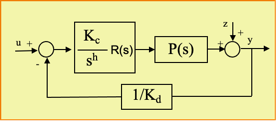

Dato il sistema in figura con:


$$P(s)=\frac{18(s^2/40^2+1.8s/40+1)(s/400+1)}{(s/20+1)(s/200+1)^2}
\\
Kd=3$$


si risponda alle seguenti domande:

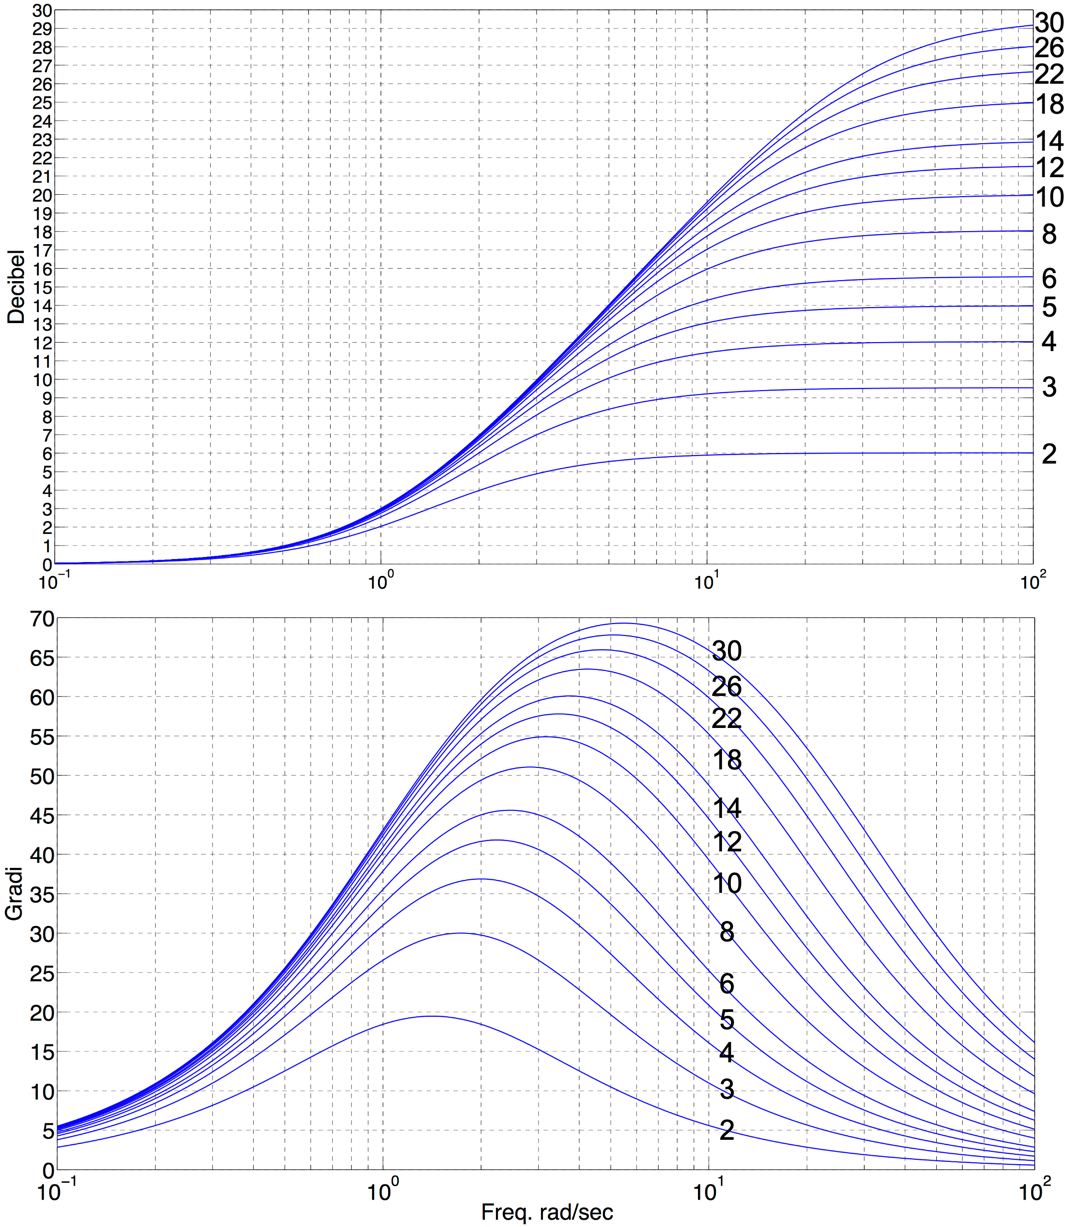

# 1 - Determinazione di h e Kc:

#### *Determinare il valore di h e Kc tale che per ****u(t)=2*delta_3(t) (ingresso a parabola),  e<=0.003334***

syms Kc % variabile simbolica da trovare nell'equazione con vpasolve
h=2 % numero di integratori dato l'ingresso u(t)

h = 2

Kd=3 % ce lo da il prof

Kd = 3

emax=0.003334 % e<=0.003334

emax = 0.0033

Kp=18 % cooefficiente di P(s)

Kp = 18

eq1= Kd^2/(Kc*Kp)*2==emax % sempre la stessa tranne il due che è il coefficiente di u(t)

$$eq1 = \frac{1}{\mathrm{Kc}}=\frac{960960074089807}{288230376151711744}$$

Kc=double(vpasolve(eq1,Kc)) % valore associato alla variabile simbolica trovato nell'equazione 

Kc = 299.9400

Kc=300 % approssimazione

Kc = 300

# 2 - Determinazione valori di Kc per stabilità

#### *Determinare con il luogo delle radici il range dei Kc ammissibili (se possibile) e, in caso contrario, scegliere il Kc che soddisfa **solo** la specifica precedente.*

s=tf([1 0],1) % s

s =
 
  s
 
Continuous-time transfer function.



P=Kp*(s^2/40^2+1.8/40*s+1)*(s/400+1)/((s/20+1)*(s/200+1)^2) % P(s), Kp lo leggo dal testo di P(s)

P =
 
  1.44e07 s^3 + 6.797e09 s^2 + 4.378e11 s + 9.216e12
  --------------------------------------------------
   640000 s^3 + 2.688e08 s^2 + 3.072e10 s + 5.12e11
 
Continuous-time transfer function.



C=1/s^2 % s^-h

C =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



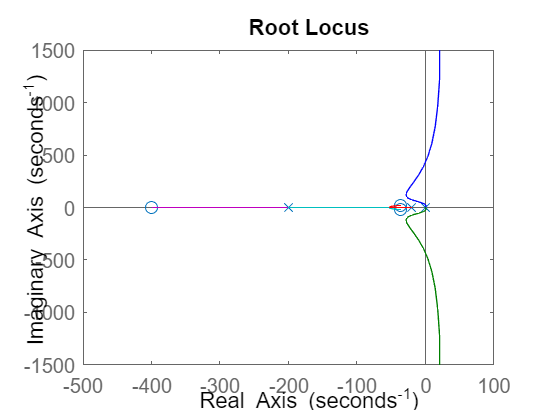

rlocus(C*P/Kd) % luogo pos

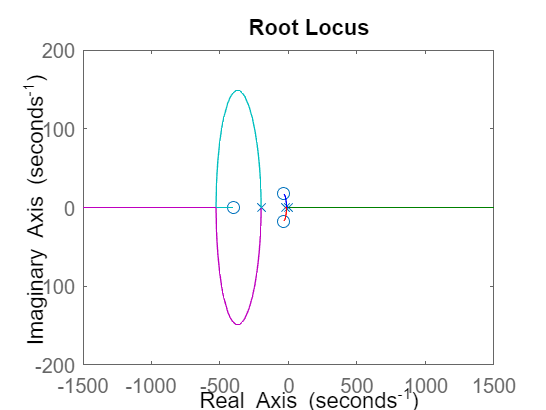

rlocus(-C*P/Kd) % luogo neg

il sistema risulta stabile a ciclo chiuso per 136<Kc<22500. Pertanto con Kc=300 non avremo problemi iniziali di stabilità.

# 3 - Sintesi rete correttrice

#### *Determinare una rete anticipatrice in modo tale che: *

- *l'errore di riproduzione di una sinusoide unitaria in ingresso sia minore (in uscita) di *`0.6`* fino a *`w=20 ``rad/sec`*, *

- `wt<=100 rad/sec rad/sec` 

- `m_fase>=60°`

# a) Verifica specifica sulla riproduzione di una sinusoide

% NON toccare
finestra=20*log10(Kd/0.6) % 20 * log10(x) = x|dB ; 0.6 (emax) e kd sono dati dal testo

finestra = 13.9794

wmax=20 % dato dal testo

wmax = 20

# b) Analisi dei diagrammi a ciclo aperto

tracciamo i vari diagrammi della funzione a ciclo aperto e ciclo chiuso prima della correzione

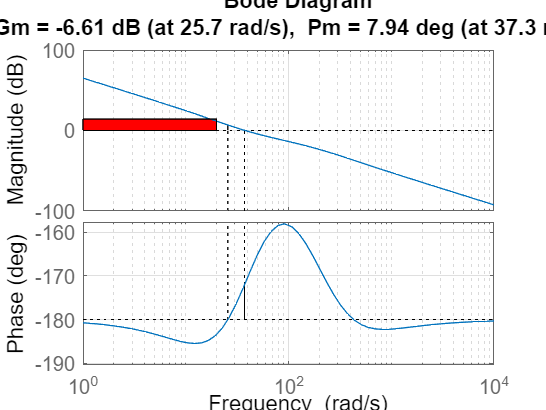

%figure
wmin=1; % lo dobbiamo mettere noi, di solito sempre 1
margin(P*C*Kc/Kd,{wmin,10000}),grid on  % lo dobbiamo mettere noi
hold on  % lo dobbiamo mettere noi
a=gcf;
a.CurrentAxes=a.Children(3); % per disegnare nel subplot giusto
% parametri: x iniziale, y iniziale, ampiezza, altezza
r=rectangle('Position',[wmin,0,wmax-wmin,finestra]);  % i parametri li dobbiamo mettere noi
r.FaceColor='red';
hold off  % lo dobbiamo mettere noi

# c) Scelta rete compensatrice

m=8; % m > 1
tau=6/100 % omega della carta (quella relativa alla rete corretrice) / omega di bode (quella che fornisce il prof)

tau = 0.0600

R=(s*tau+1)/(s*tau/m+1) % m a denominatore di R(s) ANTICIPATRICE, altrimenti attenuatrice

R =
 
  0.48 s + 8
  ----------
  0.06 s + 8
 
Continuous-time transfer function.



dalla analisi del ciclo aperto noto che per soddisfare le specifiche dovrei aumentare il modulo di 14.4 decibel e la fase di almeno 38 gradi. Utilizzo, dalla carta, m=8 e tau=6

Successivamente sposto la rete a sinistra di poco per migliorare il margine di fase. 

# 4 - Confronto ciclo chiuso con/senza correzione

#### *confrontare gli andamenti del ciclo chiuso con e senza correzione nei vari ****diagrammi***

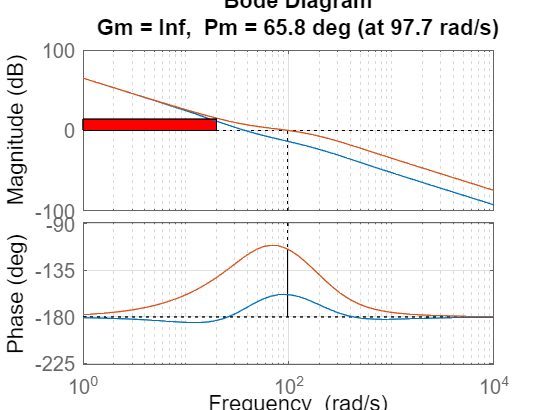

% copia e incolla di quello di prima, aggiungo Bode a ciclo aperto all'inizio e Nichols a
% alla fine

wmin=1;
bode(P*C*Kc/Kd,{wmin,10000}),grid on
hold on
margin(R*P*C*Kc/Kd,{wmin,10000}),grid on % qui c'è R(s)


a=gcf;
a.CurrentAxes=a.Children(3); % per disegnare nel subplot giusto
% parametri: x iniziale, y iniziale, ampiezza, altezza
r=rectangle('Position',[wmin,0,wmax-wmin,finestra]);
r.FaceColor='red';
hold off

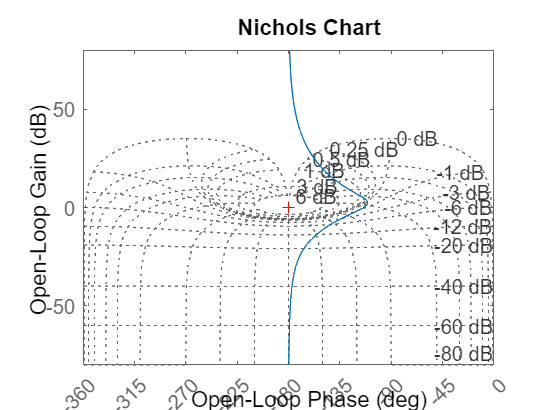


nichols(R*P*C*Kc/Kd),ngrid % ngrid -> nichols ; qui c'è R(s)

# 5 - Parametri caratteristici

#### **Valutare modulo alla risonanza, banda passante, tempo di salita e sovraelongazione dopo la correzione**

W=feedback(R*P*C*Kc,1/Kd) % catena diretta e di controreazione

W =
 
               2.074e09 s^4 + 1.013e12 s^3 + 7.935e13 s^2 + 2.378e15 s + 2.212e16
  ---------------------------------------------------------------------------------------------
  38400 s^6 + 2.125e07 s^5 + 4.685e09 s^4 + 6.142e11 s^3 + 3.055e13 s^2 + 7.926e14 s + 7.373e15
 
Continuous-time transfer function.



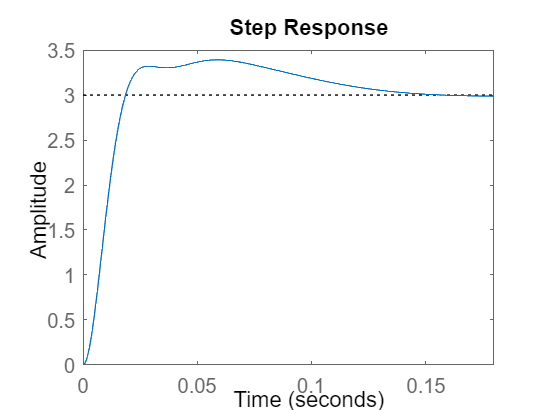

step(W) % W(s) con gradino

stepinfo(W) % info W(s) con gradino

ans = struct with fields:
         RiseTime: 0.0123
    TransientTime: 0.1281
     SettlingTime: 0.1281
      SettlingMin: 2.7060
      SettlingMax: 3.3923
        Overshoot: 13.0759
       Undershoot: 0
             Peak: 3.3923
         PeakTime: 0.0589


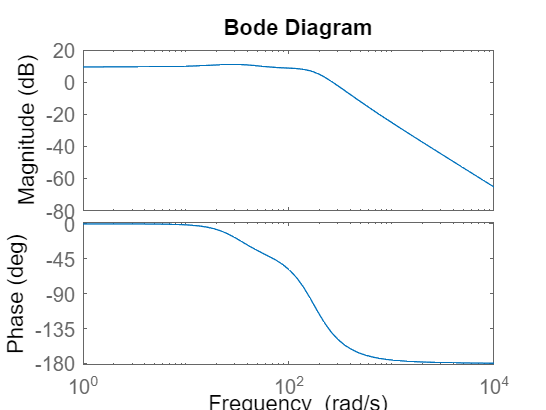

bode(W) % Bode di W(s)


% margine di fase e omega di taglio: lo leggiamo dal grafico superiore dato da margin(R*P*C*Kc/Kd,{wmin,10000}),grid on.  
% modulo alla risonanza: differenza valore di picco e valore iniziale.
% overshoot: su stepinfo.
% risetime: su stepinfo.
% banda passante: ascissa corrispondente al valore di regime in dB -3 dB (Bode).

Il margine di fase viene 64° e l'omega di taglio 99.9 rad/sec

Il modulo alla risonanza 1.5 dB 

Dalla risposta alla gradino, la sovraelongazione vale il 12%

Il tempo di salita è 0.0121 sec

la banda passante è a 178 rad/sec

# 6 - Massimo ritardo

#### **Valutare infine il massimo ritardo finito sopportabile dal sistema prima che il margine di fase scenda sotto i 10°**

syms d % var simbolica come prima...
wt=99.9 % 100

wt = 99.9000

vpasolve(wt*d==(64-10)*pi/180) % 64 gradi è il margine di fase, 10 lo da il testo e w di taglio con il margine di fase lo leggiamo immediatamente sopra; * pi / 180 per convertire in radianti

$$ans = 0.0094342121729423220374253555053439$$

Il massimo ritardo è di 0.0094342121729423220374253555053439 secondi

# 7 - Valutare l'effetto di un campionamento del controllore 

**Traccciare il diagramma di Bode dell'organo di tenuta con w_c pari sia al doppio della banda passante sia x volte tanto determinando x in modo da avere un margine di fase complessivo di almeno 58°.** 

% ZOH con Shannon
% N.B. = x minimo 10 solitamente e se è un x buono ricostruiremo bene il
% segnale con ingresso a gradino (grafico step response).
w_c1=2*178 % doppio della banda passante

w_c1 = 356

Tc1=2*pi/w_c1 % Tc = 2pi/Wc

Tc1 = 0.0176

zoh1=(1-exp(-s*Tc1))/s; % ZOH(S) = (1 - e^(-s * Tc1)) / s

w_c2=16*178 % lo scriviamo dopo, 16 è il valore giusto per regolare ; x = 16

w_c2 = 2848

Tc2=2*pi/w_c2 % ricalcolo Tc

Tc2 = 0.0022

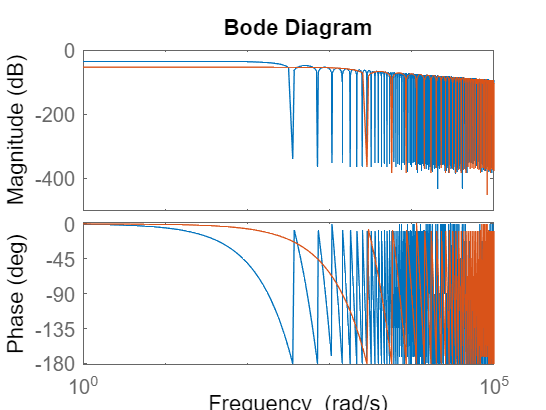

zoh2=(1-exp(-s*Tc2))/s; % ricalcolo ZOH(s)

% confronto tramite Bode i 2 risultati :

bode(zoh1)
hold on
%---------
bode(zoh2)
hold off

**Verificare come i margini di stabilità e l'omega di taglio vengano modificati**

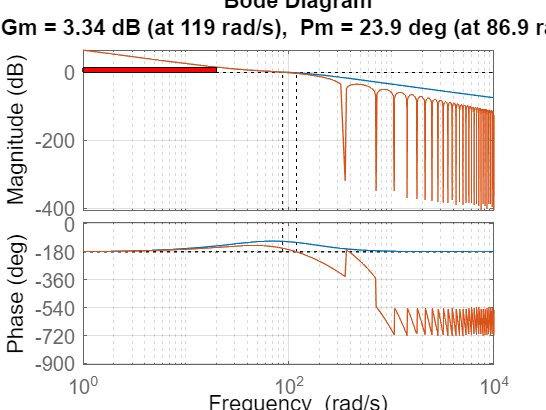


% copia e incolla di quello sopra, ma aggiungo * zoh1/Tc1 con margin

% NON necessario
bode(R*P*C*Kc/Kd,{wmin,10000})
hold on
margin(R*P*C*Kc/Kd*zoh1/Tc1,{wmin,10000}),grid on

a=gcf;
a.CurrentAxes=a.Children(3); % per disegnare nel subplot giusto
% parametri: x iniziale, y iniziale, ampiezza, altezza
r=rectangle('Position',[wmin,0,wmax-wmin,finestra]);
r.FaceColor='red';
hold off

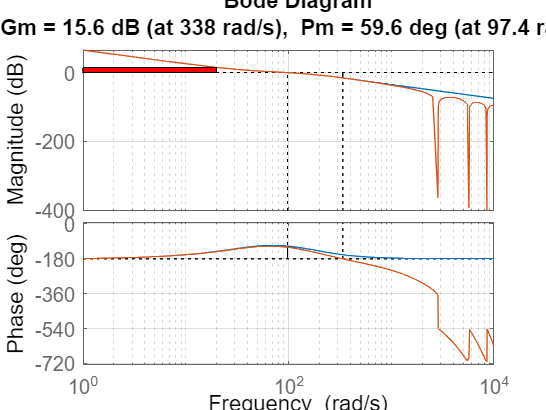

 
% copia e incolla di quello sopra, ma aggiungo * zoh2/Tc2 con margin

bode(R*P*C*Kc/Kd,{wmin,10000})
hold on
margin(R*P*C*Kc/Kd*zoh2/Tc2,{wmin,10000}),grid on

a=gcf;
a.CurrentAxes=a.Children(3); % per disegnare nel subplot giusto
% parametri: x iniziale, y iniziale, ampiezza, altezza
r=rectangle('Position',[wmin,0,wmax-wmin,finestra]);
r.FaceColor='red';
hold off

**Confrontare le risposte al gradino con e senza l'organo di tenuta**

% W(s) aggiungendo *zoh1/Tc1 e *zoh2/Tc2 e poi li confronto con ingresso a
% gradino

W1=feedback(R*P*C*Kc*zoh1/Tc1,1/Kd)

W1 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1      -553.3      -406.2      -219.7      -50.86           0           0           0
   x2         256           0           0           0           0           0           0
   x3           0         128           0           0           0           0           0
   x4           0           0          64           0           0           0           0
   x5           0           0           0           1           0           0           0
   x6           0           0           0           0           1           0           0
   x7           0      -7.781      -29.71      -36.35       -1089  -1.013e+04           0
 
  B = 
          u1
   x1      0
   x2      0
   x3      0
   x4      0
   x5      0
   x6      0
   x7  56.66
 
  C = 
          x1     x2     x3     x4     x5     x6     x7
   y1      0  0.412  1.573  1.924  57.67  536.4      0
 
  D = 
       u1
   y1   0
 
  (

W2=feedback(R*P*C*Kc*zoh2/Tc2,1/Kd)

W2 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1      -553.3      -406.2      -219.7      -50.86           0           0           0
   x2         256           0           0           0           0           0           0
   x3           0         128           0           0           0           0           0
   x4           0           0          64           0           0           0           0
   x5           0           0           0           1           0           0           0
   x6           0           0           0           0           1           0           0
   x7           0      -62.25      -237.6      -290.8       -8713  -8.105e+04           0
 
  B = 
          u1
   x1      0
   x2      0
   x3      0
   x4      0
   x5      0
   x6      0
   x7  453.3
 
  C = 
          x1     x2     x3     x4     x5     x6     x7
   y1      0  0.412  1.573  1.924  57.67  536.4      0
 
  D = 
       u1
   y1   0
 
  (

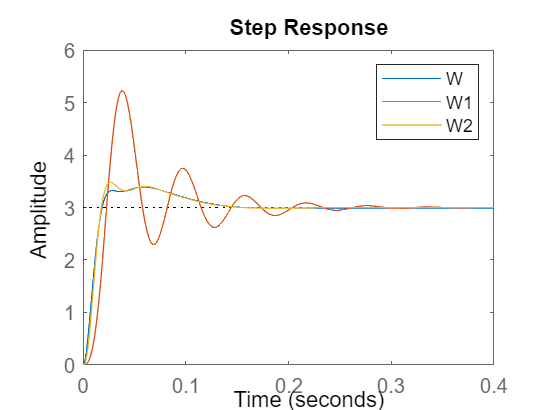


step(W)
hold on
step(W1)
step(W2)
hold off
legend

% N.B = guardare la richiesta e il pshase margin di ZOH1(S) e ZOH2(S)
% N.B. = step nel tempo

come si vede bisogna scegliere una w_c almeno 16 volte maggiore della banda passante.

% Discretizzazione controllore al variare di Tc

Cs = R * Kc * C % controllore, guarda il sistema ^

Cs =
 
    144 s + 2400
  ----------------
  0.06 s^3 + 8 s^2
 
Continuous-time transfer function.



Cz1 = c2d(Cs, Tc1, 'tustin')

Cz1 =
 
  0.0985 z^3 + 0.1238 z^2 - 0.04798 z - 0.07324
  ---------------------------------------------
      z^3 - 1.919 z^2 + 0.8377 z + 0.08115
 
Sample time: 0.017649 seconds
Discrete-time transfer function.



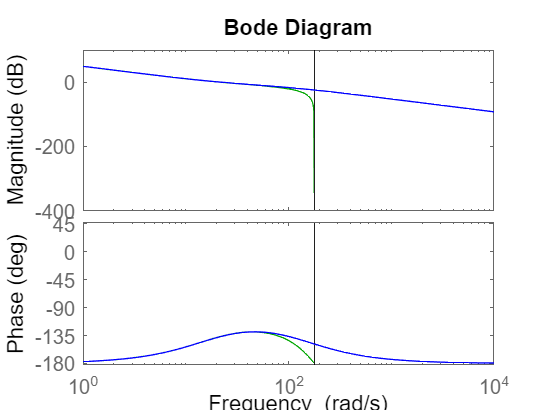

bode(Cz1, 'g')
hold on
bode(Cs, 'b')
hold off